# modèle identifié

% résultat identification linéaire sans charge
% x = [Dlambda lambda Dphi phi]'
c =  [-21.1679    0.0036  992.6779    0.3390   -1.1775 -102.5803  -15.2604   -0.0230   -0.0059]

c =   -21.1679    0.0036  992.6779    0.3390   -1.1775 -102.5803  -15.2604   -0.0230   -0.0059



A = [c(1) 0 0 c(2);
    1   0 0 0;
    c(4) 0 c(5) c(6);
    0   0 1 0];
B = [c(3);0;c(7);0];
C = [0 1 0 0;
     0 0 0 1];

vp_obs = [-41 -42 -43 -44]

vp_obs =    -41   -42   -43   -44


L= place(A',C',vp_obs)'

L = 1.0e+03 *

    0.4486    0.0102
    0.0636    0.0005
    0.1010    1.6154
    0.0023    0.0841




eig(A)

ans =    0.0000 + 0.0000i
 -21.1679 + 0.0000i
  -0.5888 +10.1111i
  -0.5888 -10.1111i


Bd = -B;
Abar = [A Bd;zeros(1,4) 0]

Abar =   -21.1679         0         0    0.0036 -992.6779
    1.0000         0         0         0         0
    0.3390         0   -1.1775 -102.5803   15.2604
         0         0    1.0000         0         0
         0         0         0         0         0


Bbar = [B;0];
Cbar = [C zeros(2,1)];
vp_obs = [-11 -12 -13 -14 -15]-100

vp_obs =   -111  -112  -113  -114  -115


Lbar = place(Abar',Cbar',vp_obs)'

Lbar = 1.0e+04 *

    3.1508   -0.4526
    0.0318   -0.0022
   -0.0283    1.2468
   -0.0001    0.0225
   -0.1449    0.0284


[wn,zeta,p]= damp(A)

wn =          0
   21.1679
   10.1282
   10.1282


zeta =    -1.0000
    1.0000
    0.0581
    0.0581


p =    0.0000 + 0.0000i
 -21.1679 + 0.0000i
  -0.5888 +10.1111i
  -0.5888 -10.1111i


wn = 10;zeta=0.8;
p1 = -wn*zeta+1i*wn*sqrt(1-zeta^2)

p1 = -8.0000 + 6.0000i

vp_c = [-1 -21, p1,p1']

vp_c =   -1.0000 + 0.0000i -21.0000 + 0.0000i  -8.0000 + 6.0000i  -8.0000 - 6.0000i


F = place(A,B,vp_c)

F =     0.0062    0.0206   -0.6241  -21.3771


G = (C(1,:)*(-A+B*F)^-1*B)^-1

G = 0.0206

Te = 0.005;

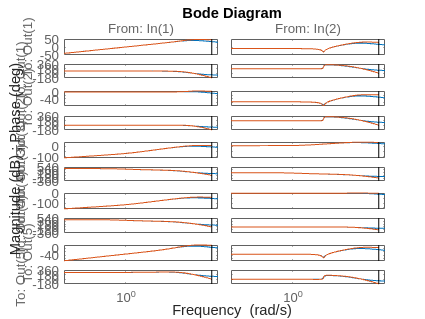


obs = ss(Abar-Lbar*Cbar,Lbar,eye(5),0);
obs_d = ss(eye(5)+Te*(Abar-Lbar*Cbar),Te*Lbar,eye(5),0,Te);
bode(obs,obs_d)